# Exponentes de Lyapunov

# Ecuación Variacional del sistema de Lorenz

- Una **ecuación variacional** describe cómo **evolucionan las perturbaciones** (o generalmente, el **volumen del espacio de fase**) a lo largo de una trayectoria. 

- Estas ecuaciones son cruciales para entender cómo las trayectorias cercanas se separan o se acercan en el espacio fase.

Consideramos el siguiente sistema de Lorenz (1963):

#### $\dot{v} =\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f_x \left(x,y,z\right)\\
f_y \left(x,y,z\right)\\
f_z \left(x,y,z\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sigma \;\left(y-x\right)\\
r\;x-y-x\;z\\
-b\;z+x\;y
\end{array}\right\rbrack$    (1)

donde los parámteros $\sigma ,\;b\;\;y\;\;r$ son reales positivos. Los valores adoptados por Lorenz, son $\sigma =10,b=\frac{8}{3}\;y\;r=28\ldotp$ 

- Para un sistema de dimensión $n$, hace falta $n^2$ derivadas parciales para describir todas las variaciones del sistema. 

- La matriz Jacobiana devuelve dichas variaciones:

#### 
$$D\;f=\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial x}f_x  & \frac{\partial }{\partial y}f_x  & \frac{\partial }{\partial z}f_x \\
\frac{\partial }{\partial x}f_y  & \frac{\partial }{\partial y}f_y  & \frac{\partial }{\partial z}f_y \\
\frac{\partial }{\partial x}f_z  & \frac{\partial }{\partial y}f_z  & \frac{\partial }{\partial z}f_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\sigma \; & \sigma \; & 0\\
r-z & -1 & -x\\
y & x & -b
\end{array}\right\rbrack$$


- El siguiente paso es decribir las variaciones. 

- Utilizando la notación $\delta_{\textrm{xy}}$** que hace referencia a la variación en la dirección **$x$** generada por una variación en la dirección **$y$, La matriz de todas las variaciones viene dada por:

#### 
$$\left\lbrack \delta \;\right\rbrack =\left\lbrack \begin{array}{ccc}
\delta_{\textrm{xx}}  & \delta_{\textrm{yx}}  & \delta_{\textrm{zx}} \\
\delta_{\textrm{xy}}  & \delta_{\textrm{yy}}  & \delta_{\textrm{zy}} \\
\delta_{\textrm{xz}}  & \delta_{\textrm{yz}}  & \delta_{\textrm{zz}} 
\end{array}\right\rbrack$$


- **La ecuación variacional es entonces**:

#### 
$$\left\lbrack \dot{\delta \;} \right\rbrack =D\;f\;\left\lbrack \delta \;\right\rbrack$$


- Se trata entonces de resolver la ecuación variacional y el sistema de forma simultanea. 

- Para ello, trabajamos con un vector de estado aumentado dado por:

#### 
$$\left(x,y,z,\delta_{\textrm{xx}} ,\delta_{\textrm{xy}} ,\delta_{\textrm{xz}} ,\delta_{\textrm{yx}} ,\delta_{\textrm{yy}} ,\delta_{\textrm{yz}} ,\delta_{\textrm{zx}} ,\delta_{\textrm{zy}} ,\delta_{\textrm{zz}} \;\right)$$


- Las ecuaciones diferenciales que describen este sistema aumentado son:


$$\begin{array}{l}
\dot{x} =\sigma \;\left(y-x\right)\\
\dot{y} =r\;x-y-x\;z\\
\dot{z} =-b\;z+x\;y\\
{\dot{\delta \;} }_{\textrm{xx}} =-\sigma \;\delta_{\textrm{xx}} +\sigma \;\delta_{\textrm{xy}} \\
{\dot{\delta \;} }_{\textrm{xy}} =\left(r-z\right)\;\delta_{\textrm{xx}} -\delta_{\textrm{xy}} -x\delta_{\textrm{xz}} \\
{\dot{\delta \;} }_{\textrm{xz}} =y\delta_{\textrm{xx}} +x\delta_{\textrm{xy}} -b\delta_{\textrm{xz}} \\
{\dot{\delta \;} }_{\textrm{yx}} =-\sigma \;\delta_{\textrm{yx}} +\sigma \;\delta_{\textrm{yy}} \\
{\dot{\delta \;} }_{\textrm{yy}} =\left(r-z\right)\;\delta_{\textrm{yx}} -\delta_{\textrm{yy}} -x\delta_{\textrm{yz}} \\
{\dot{\delta \;} }_{\textrm{yz}} =y\delta_{\textrm{yx}} +x\delta_{\textrm{yy}} -b\delta_{\textrm{yz}} \\
{\dot{\delta \;} }_{\textrm{zx}} =-\sigma \;\delta_{\textrm{zx}} +\sigma \;\delta_{\textrm{zy}} \\
{\dot{\delta \;} }_{\textrm{zy}} =\left(r-z\right)\;\delta_{\textrm{zx}} -\delta_{\textrm{zy}} -x\delta_{\textrm{zz}} \\
{\dot{\delta \;} }_{\textrm{zz}} =y\delta_{\textrm{zx}} +x\delta_{\textrm{zy}} -b\delta_{\textrm{zz}} 
\end{array}$$


% Limpiar el espacio de trabajo y cerrar todas las figuras previas
clc; 
clear all;
close all;

% Definir el número de iteraciones y el tiempo de simulación
n = 100;  % Número de iteraciones para calcular el exponente de Lyapunov
T = 100; % Tiempo de simulación 

% Parámetros del modelo de Lorenz
sigma = 10;
b = 8/3;
r = 28;

% Calcular el exponente de Liapunov
L = lle_Lorenz(n, sigma, r, b, T); % Función definida más adelante
L = log(L) / T; % Promedio temporal de los exponentes de Lyapunov
t = (1:n)'; % Vector de tiempo para graficar


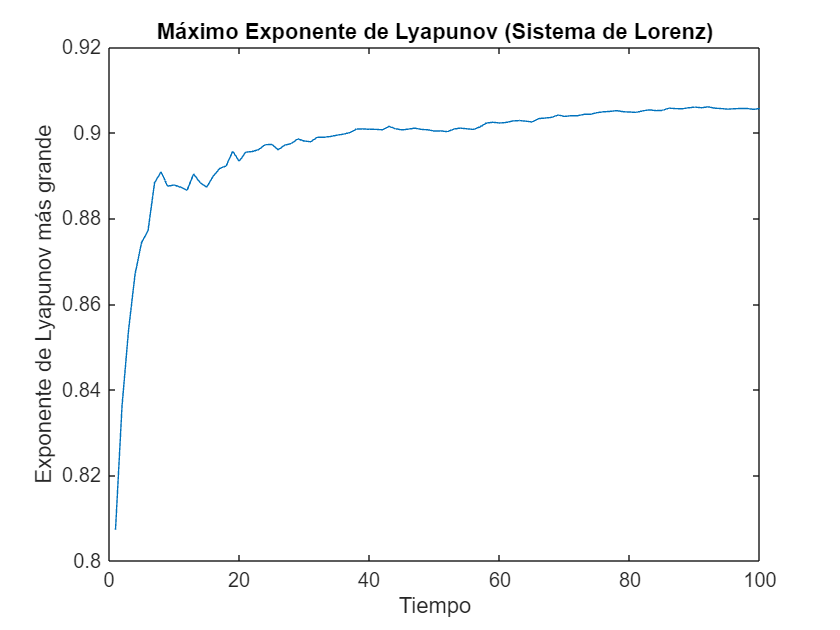

% Graficar el exponente de Lyapunov promediado en el tiempo
plot(t, cumsum(L) ./ t);
xlabel('Tiempo');
ylabel('Exponente de Lyapunov más grande');
title('Máximo Exponente de Lyapunov (Sistema de Lorenz)');

function F = LorenzPerturbado(t, X, sigma, r, b)
    % LORENZPERTURBADO Ecuaciones del sistema de Lorenz perturbado
    % Esta función calcula las derivadas del sistema de Lorenz y sus perturbaciones
    % Entrada:
    %   t - tiempo (no utilizado, pero necesario para funciones ODE en MATLAB)
    %   X - vector de estado (contiene las variables del sistema y las perturbaciones)
    %   sigma - parámetro sigma del sistema de Lorenz
    %   r - parámetro r del sistema de Lorenz
    %   b - parámetro b del sistema de Lorenz
    % Salida:
    %   F - vector de derivadas
    % Desempaquetar las variables del estado y las perturbaciones
    x = X(1); 
    y = X(2); 
    z = X(3);       
    deltaxy = [X(4), X(7), X(10); 
               X(5), X(8), X(11);
               X(6), X(9), X(12)];
    
    % Inicializar el vector de salida
    F = zeros(12, 1);
    
    % Ecuaciones del sistema de Lorenz
    F(1) = sigma * (y - x);
    F(2) = -x * z + r * x - y;
    F(3) = x * y - b * z;
    
    % Matriz Jacobiana
    J = [-sigma, sigma, 0;
         r - z, -1, -x;
         y, x, -b];
      
    % Ecuaciones diferenciales para las perturbaciones
    F(4:12) = J * deltaxy;
end


% Función para calcular el exponente de Liapunov del sistema de Lorenz
function L = lle_Lorenz(n, sigma, r, b, T)
    % Inicialización del vector para almacenar las normas de las perturbaciones
    L = zeros(n, 1);
   
    % Configuración de las opciones de la función de integración
    options = odeset('RelTol', 1e-8, 'AbsTol', 1e-8);
    % Generar una condición inicial aleatoria para el sistema perturbado
    y0 = rand(12, 1);  
    % Normalizar el vector de desviación
    y0(4:end) = y0(4:end) / norm(y0(4:end));      

    % Iteración para calcular las normas de las perturbaciones
    for k = 1:n       
        % Resolver las ecuaciones diferenciales del sistema perturbado
        [~, y] = ode45(@(t, y) LorenzPerturbado(t, y, sigma, r, b), [0, T], y0, options);
        y0=y(end,:)';
        % Almacenar la norma del vector de desviación en cada iteración
        L(k) = norm(y0(4:end));
        % Normalizar el vector de desviación para la siguiente iteración
        y0(4:end) = y0(4:end) / L(k);        
    end
end
